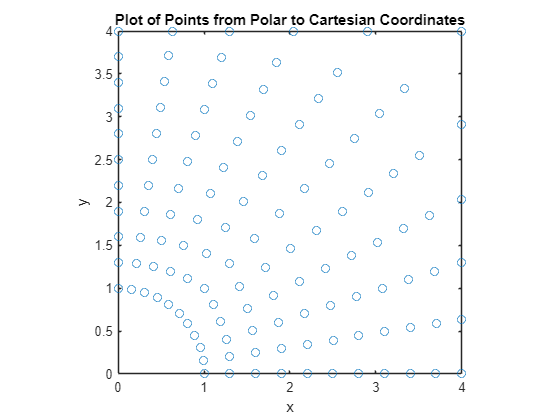

clear
clc
% define some important params
% define size 
%
num_horizontal = 10;
num_vertical = 10;
%}
%{
num_horizontal = 2;
num_vertical = 2;
%}
% define thickness
thickness = 1;

% E, v and D
E = 10*10^6;
v = 0.3;
D = E/(1-v^2)*[1, v, 0; v, 1, 0; 0, 0, (1-v)/2];

% object param
L = 4;
r_circle = 1;
dtheta = (pi/2) * (1/num_vertical);
dr = (L-r_circle) / num_horizontal;

% weigths
W_1 = 1;
W_2 = 1;

% BC_index initialization
BC_disp_index = [];
BC_disp_val = [];
BC_force_index = [];

BC_force_val_x = [];
BC_force_val_y = [];
for i = 1:(num_vertical/2) + 1
    if i == 1 || i == num_vertical/2 + 1
        force_x = 10*L/(num_vertical) * thickness;
        force_y = 3*L/(num_vertical) * thickness;
        BC_force_val_x = [BC_force_val_x, force_x];
        BC_force_val_y = [BC_force_val_y, force_y];
    else          
        force_x = 10*L/(num_vertical) * thickness * 2;
        force_y = 3*L/(num_vertical) * thickness * 2;
        BC_force_val_x = [BC_force_val_x, force_x];
        BC_force_val_y = [BC_force_val_y, force_y];
    end
end

BC_force_val = [BC_force_val_x, BC_force_val_y];
%}

%{
% border coord
x_border_coord = [];
y_border_coord = [];
for i = 1 : num_vertical
    y = 0 + (i-1) * (L/num_vertical);
    y_border_coord = [y_border_coord, y];
end
%}

% initialize k_global
dimension = (num_vertical + 1) * (num_horizontal + 1);
K_global = zeros(dimension*2, dimension*2);
F = zeros(dimension*2, 1);

% Define the size of the matrix
x_coord = [];
y_coord = [];
num = num_vertical/2;
rate = -0.066 * num_horizontal + 0.682;
% Loop through theta and r values
for i = 1 : num_vertical+1
    theta = (i-1)*dtheta;
    if i <= 1+(num_vertical/2)
        dr = dr * (1 + rate*(i-1));
    end
    if i > 1+(num_vertical/2)
        dr = dr / (1 + rate*(num));
        num = num - 1;
    end
    for j = 1 : num_horizontal
        r = r_circle + (j-1)*(dr);
        % convert polar to cartesian
        x = r * cos(theta);
        y = r * sin(theta);
        x_coord = [x_coord, x];
        y_coord = [y_coord, y];

        % check if point is at border
        if j == num_horizontal && i < (num_vertical/2)+2
            y_border_coord = tan(theta)*L;
            x_coord = [x_coord, 4];
            y_coord = [y_coord, y_border_coord];
        end
        if j == num_horizontal && i >= (num_vertical/2)+2
            x_border_coord = L / tan(theta);
            x_coord = [x_coord, x_border_coord];
            y_coord = [y_coord, 4];
        end
        
    end
end

% make small values to zero
for i = 1:length(x_coord)
    if x_coord(i) < 1*10^-5
        x_coord(i) = 0;
    end
end

% Plot points
plot(x_coord, y_coord, 'o');
xlabel('x');
ylabel('y');
title('Plot of Points from Polar to Cartesian Coordinates');
% Set aspect ratio to be equal and set both axes to 4
axis equal;
xlim([0, 4]);
ylim([0, 4]);


% Reshape x_coord into a 11x11 matrix
x_coord_2d = reshape(x_coord, num_horizontal+1, [])';
y_coord_2d = reshape(y_coord, num_horizontal+1, [])';

% 
e_info = struct('x_coord', cell(1, num_horizontal^2), 'y_coord', cell(1, num_vertical^2));

% assign coordinates to elelemt , CCW 
%
for i = 1:num_horizontal
    for j = 1:num_vertical
        % Extract the x, y coordinates for the current rectangle
        x_coord = x_coord_2d(i:i+1, j:j+1);
        y_coord = y_coord_2d(i:i+1, j:j+1);
        
        % Assign the coordinates to the corresponding e_info element
        index = (i-1)*num_vertical + j;
        %{
        e_info(index).x_coord = x_coord(:);
        e_info(index).y_coord = y_coord(:);
        %}

        % CCW assign from bottom left, be careful even when vertical, have
        % to think as layed downned
        %
        e_info(index).x_coord = [x_coord(1,1); x_coord(1,2); x_coord(2,2); x_coord(2,1)];
        e_info(index).y_coord = [y_coord(1,1); y_coord(1,2); y_coord(2,2); y_coord(2,1)];
        %}
    end
end
%}

% define mapping xi and eta value
% also CCW mapping be carful with direction
xi_eta_pairs = [
                -1/sqrt(3), -1/sqrt(3);
                 1/sqrt(3), -1/sqrt(3);
                 1/sqrt(3),  1/sqrt(3);
                -1/sqrt(3),  1/sqrt(3)
                ];

[row_coord_local, ~] = size(xi_eta_pairs);

row_in_2d_coord = 1;
for element_num = 1:numel(e_info)
    K = 0;
    e = e_info(element_num);
    x_local_coord = e.x_coord;
    y_local_coord = e.y_coord;
    x_1 = x_local_coord(1); % bot_left
    x_2 = x_local_coord(2); % bot_right
    x_3 = x_local_coord(3); % top_right
    x_4 = x_local_coord(4); % top_left
    y_1 = y_local_coord(1); % bot_left
    y_2 = y_local_coord(2); % bot_right
    y_3 = y_local_coord(3); % top_right
    y_4 = y_local_coord(4); % top_left
    
    % local K
    for i = 1:row_coord_local
        xi = xi_eta_pairs(i, 1);
        eta = xi_eta_pairs(i, 2);
        % jacobian matrix
        % eta is n-like letter, xi is the other one
        % |J(xi, eta)|
        J_xi_eta = [0, 1-eta, eta-xi, xi-1;
                    eta-1, 0, xi+1, -xi-eta;
                    xi-eta, -xi-1, 0, eta+1;
                    1-xi, xi+eta, -eta-1, 0];
        J_det = (1/8) * x_local_coord' * J_xi_eta * y_local_coord;
        
        % dN/dxi and dN/deta
        dN1_dxi = (-1/4) * (1-eta);
        dN1_deta = (-1/4) * (1-xi);
    
        dN2_dxi = (1/4) * (1-eta);
        dN2_deta = (-1/4) * (1+xi);
    
        dN3_dxi = (1/4) * (1+eta);
        dN3_deta = (1/4) * (1+xi);
    
        dN4_dxi = (-1/4) * (1+eta);
        dN4_deta = (1/4) * (1-xi); 
        
        % something wrong with a b c d 
        %{
        % a, b, c, d terms in inverse jacob
        a = (1/4) * [y_1*(xi-1) + y_2*(-1-xi) + y_3*(1+xi) + y_4*(1-xi)];
        b = (1/4) * [y_1*(eta-1) + y_2*(1-eta) + y_3*(1+eta) + y_4*(-1-eta)];
        c = (1/4) * [x_1*(eta-1) + x_2*(1-eta) + x_3*(1+eta) + x_4*(-1-eta)];
        d = (1/4) * [x_1*(xi-1) + x_2*(-1-xi) + x_3*(1+xi) + x_4*(1-xi)];
        
        % B(xi, eta)
        B_1 = [ a*dN1_dxi - b*dN1_deta,     0; 
                0,                          c*dN1_dxi - d*dN1_deta;
                c*dN1_dxi - d*dN1_deta,     a*dN1_dxi - b*dN1_deta];
    
        B_2 = [ a*dN2_dxi - b*dN2_deta,     0; 
                0,                          c*dN2_dxi - d*dN2_deta;
                c*dN2_dxi - d*dN2_deta,     a*dN2_dxi - b*dN2_deta];
    
        B_3 = [ a*dN3_dxi - b*dN3_deta,     0; 
                0,                          c*dN3_dxi - d*dN3_deta;
                c*dN3_dxi - d*dN3_deta,     a*dN3_dxi - b*dN3_deta];
    
        B_4 = [ a*dN4_dxi - b*dN4_deta,     0; 
                0,                          c*dN4_dxi - d*dN4_deta;
                c*dN4_dxi - d*dN4_deta,     a*dN4_dxi - b*dN4_deta];
        
        B = (1/J_det) * [B_1, B_2, B_3, B_4];
        %}

        % calculate Inverse of J directly
        J(1,1) = [dN1_dxi, dN2_dxi, dN3_dxi, dN4_dxi]*[x_1;x_2;x_3;x_4];
        J(1,2) = [dN1_dxi, dN2_dxi, dN3_dxi, dN4_dxi]*[y_1;y_2;y_3;y_4];
        J(2,1) = [dN1_deta, dN2_deta, dN3_deta, dN4_deta]*[x_1;x_2;x_3;x_4];
        J(2,2) = [dN1_deta, dN2_deta, dN3_deta, dN4_deta]*[y_1;y_2;y_3;y_4];
        
        J_inv = inv(J);
        a = J_inv(1, 1);
        b = J_inv(1, 2);
        c = J_inv(2, 1);
        d = J_inv(2, 2);

        B_1 = [ a*dN1_dxi + b*dN1_deta,     0; 
                0,                          c*dN1_dxi + d*dN1_deta;
                c*dN1_dxi + d*dN1_deta,     a*dN1_dxi + b*dN1_deta];

        B_2 = [ a*dN2_dxi + b*dN2_deta,     0; 
                0,                          c*dN2_dxi + d*dN2_deta;
                c*dN2_dxi + d*dN2_deta,     a*dN2_dxi + b*dN2_deta];
        
        B_3 = [ a*dN3_dxi + b*dN3_deta,     0; 
                0,                          c*dN3_dxi + d*dN3_deta;
                c*dN3_dxi + d*dN3_deta,     a*dN3_dxi + b*dN3_deta];
        
        B_4 = [ a*dN4_dxi + b*dN4_deta,     0; 
                0,                          c*dN4_dxi + d*dN4_deta;
                c*dN4_dxi + d*dN4_deta,     a*dN4_dxi + b*dN4_deta];

        B = [B_1, B_2, B_3, B_4];
                
        K = K + B' * D * B * J_det * thickness * W_1 * W_2;
    end
    % store back local K matrix
    e_info(element_num).K = K;

    % throw local to global
    % get index of 4 points
    index_1 = element_num + (row_in_2d_coord-1);
    index_2 = element_num + (row_in_2d_coord);
    index_3 = element_num + (row_in_2d_coord + 1 + num_vertical);
    index_4 = element_num + (row_in_2d_coord + num_vertical);

    % add to BC_index if element is bounrdy displacement element
    % bottom boundry element | fix in y
    if element_num >= 1 && element_num <= num_vertical
        BC_disp_index = [BC_disp_index, index_1*2, index_2*2];
    end
    % leftside boundry index | fix in x
    if element_num >= (1+num_vertical*(num_horizontal-1)) && element_num <= num_vertical^2
        BC_disp_index = [BC_disp_index, index_3*2-1, index_4*2-1];
    end

    % add to BC_force index if element is bounrdy force element
    % right side forces | 2nd 3rd node | x-direction
    if mod(element_num, num_horizontal) == 0 && element_num <= num_horizontal*num_horizontal/2
        BC_force_index = [BC_force_index, index_2*2-1, index_3*2-1];
    end
    % top side forces | 2rd 3th node | y-direction
    if mod(element_num, num_horizontal) == 0 && element_num > num_horizontal*num_horizontal/2
        BC_force_index = [BC_force_index, index_2*2, index_3*2];
    end

    indices = [index_1*2-1, index_1*2, index_2*2-1, index_2*2, index_3*2-1, index_3*2, index_4*2-1, index_4*2];
    for local_row = 1:8
        for i = 1:length(indices)
            K_global(indices(local_row), indices(i)) = K_global(indices(local_row), indices(i)) + K(local_row, i);
        end
    end
    if mod(element_num, num_horizontal) == 0
        row_in_2d_coord = row_in_2d_coord + 1;
        disp(' ')
    end

end


BC_disp_index = unique(BC_disp_index);
BC_force_index = unique(BC_force_index);

% assign B.C index value to 0
for i = 1:length(BC_disp_index)
    BC_disp_val = [BC_disp_val, 0];
end

% assign B.C force 
for i = 1:length(BC_force_index)
    force_index = BC_force_index(i); 
    F(force_index) = BC_force_val(i);
end

Fred=F;
Kred = K_global;
for i = 1:length(BC_disp_index)
    reduc = K_global(:,BC_disp_index(i)) * BC_disp_val(i);
    Fred=Fred - reduc;

    Kred(:,BC_disp_index(i)) = 0;
    Kred(BC_disp_index(i),:) = 0;
    Kred(BC_disp_index(i),BC_disp_index(i)) = 1;
end

for i =1:length(BC_disp_index)
    Fred(BC_disp_index(i))=BC_disp_val(i);
end

displacement=Kred\Fred;
Freact=K_global*displacement;

% display corner displacements
disp('displacement for corner points: ');

displacement for corner points: 


disp('displacements for (0, 1): ');

displacements for (0, 1): 


disp(displacement(1));

   3.5328e-06



disp(displacement(2));

     0




disp('displacements for (4, 0): ');

displacements for (4, 0): 


disp(displacement(num_vertical*2-1));

   5.3935e-06



disp(displacement(num_vertical*2));

     0




disp('displacements for (0.707, 0.707): ');

displacements for (0.707, 0.707): 


(num_vertical/2) * (num_vertical+1) *2 + 1

ans = 111

(num_vertical/2) * (num_vertical+1) *2 + 2

ans = 112

disp(displacement((num_vertical/2) * (num_vertical+1) *2 + 1));

   2.4139e-06



disp(displacement((num_vertical/2) * (num_vertical+1) *2 + 2));

  -4.5050e-07




disp('displacements for (4, 4): ');

displacements for (4, 4): 


((num_vertical/2)+1) * (num_vertical+1)*2

ans = 132

((num_vertical/2)+1) * (num_vertical+1)*2-1

ans = 131

disp(displacement(((num_vertical/2)+1) * (num_vertical+1)*2));

   7.9214e-07



disp(displacement(((num_vertical/2)+1) * (num_vertical+1)*2-1));

   2.6358e-06





disp('displacements for (1, 0): ');

displacements for (1, 0): 


disp(displacement(num_horizontal*(num_vertical+1)*2+1));

     0



disp(displacement(num_horizontal*(num_vertical+1)*2+2));

  -6.7297e-07




disp('displacements for (4, 0): ');

displacements for (4, 0): 


disp(displacement(dimension*2-1));

     0



disp(displacement(dimension*2));

  -6.1963e-07



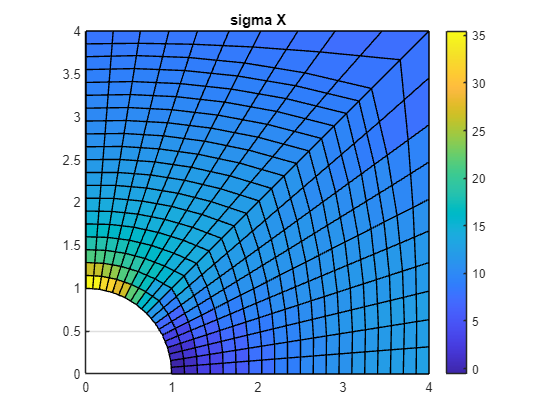

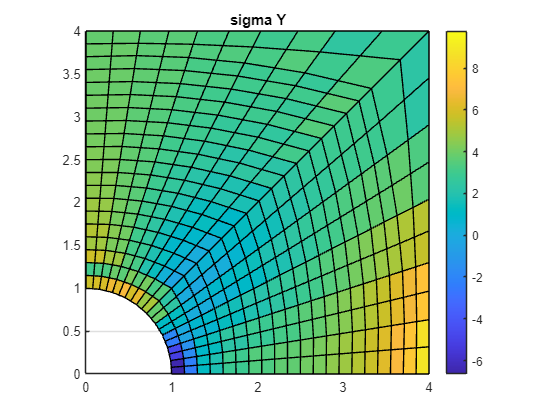



% calculate Stress  
disp_U = displacement(1:2:end);
disp_V = displacement(2:2:end);
disp_U_2d = reshape(disp_U, num_horizontal+1, [])';
disp_V_2d = reshape(disp_V, num_horizontal+1, [])';

for i = 1:num_horizontal
    for j = 1:num_vertical
        % Extract U V for the current element
        U = disp_U_2d(i:i+1, j:j+1);
        V = disp_V_2d(i:i+1, j:j+1);
        
        % Assign the U and V to the corresponding e_info element
        index = (i-1)*num_vertical + j;

        % CCW assign from bottom left, be careful even when vertical, have
        % to think as layed downned
        e_info(index).U = [U(1,1); U(1,2); U(2,2); U(2,1)];
        e_info(index).V = [V(1,1); V(1,2); V(2,2); V(2,1)];
        %}
    end
end

%{
xi_eta_pairs = [
                -sqrt(3/5), -sqrt(3/5);
                0,          -sqrt(3/5);
                sqrt(3/5),  -sqrt(3/5);

                -sqrt(3/5), 0;
                0,          0;
                sqrt(3/5),  0;

                -sqrt(3/5), sqrt(3/5);
                0,          sqrt(3/5);
                sqrt(3/5),  sqrt(3/5);
                ];
%}

xi_eta_pairs_3x3 = [
                -1, -1;
                0, -1;
                1, -1;

                -1, 0;
                0, 0;
                1, 0;

                -1, 1;
                0, 1;
                1, 1;
                ];


[row_coord_local_3x3, ~] = size(xi_eta_pairs_3x3);

for element_num = 1:numel(e_info)    
    e_info(element_num).x_3x3 = [];
    e_info(element_num).y_3x3 = [];
    e_info(element_num).stress_x = [];
    e_info(element_num).stress_y = [];
    e_info(element_num).stress_xy = [];

    e = e_info(element_num);
    stress = 0;
    x_local_coord = e.x_coord;
    y_local_coord = e.y_coord;
    U_local = e.U;
    V_local = e.V;
    disp_local = reshape([U_local(:) V_local(:)]', [], 1);

    x_1 = x_local_coord(1); % bot_left
    x_2 = x_local_coord(2); % bot_right
    x_3 = x_local_coord(3); % top_right
    x_4 = x_local_coord(4); % top_left
    y_1 = y_local_coord(1); % bot_left
    y_2 = y_local_coord(2); % bot_right
    y_3 = y_local_coord(3); % top_right
    y_4 = y_local_coord(4); % top_left
   
    u_1 = U_local(1); % bot_left
    u_2 = U_local(2); % bot_right
    u_3 = U_local(3); % top_right
    u_4 = U_local(4); % top_left
    v_1 = V_local(1); % bot_left
    v_2 = V_local(2); % bot_right
    v_3 = V_local(3); % top_right
    v_4 = V_local(4); % top_left

    for i = 1:row_coord_local_3x3
        xi = xi_eta_pairs_3x3(i, 1);
        eta = xi_eta_pairs_3x3(i, 2);
        % coordinates 
        N1 = (1/4) * (1-xi) * (1-eta);
        N2 = (1/4) * (1+xi) * (1-eta);
        N3 = (1/4) * (1+xi) * (1+eta);
        N4 = (1/4) * (1-xi) * (1+eta);
        x_local = N1*x_1 + N2*x_2 + N3*x_3 + N4*x_4;
        y_local = N1*y_1 + N2*y_2 + N3*y_3 + N4*y_4;
        % add x,y local to e_info
        e.x_3x3 = [e.x_3x3, x_local];
        e.y_3x3 = [e.y_3x3, y_local];

        % jacobian matrix
        % eta is n-like letter, xi is the other one
        % |J(xi, eta)|
        J_xi_eta = [0, 1-eta, eta-xi, xi-1;
                    eta-1, 0, xi+1, -xi-eta;
                    xi-eta, -xi-1, 0, eta+1;
                    1-xi, xi+eta, -eta-1, 0];
        J_det = (1/8) * x_local_coord' * J_xi_eta * y_local_coord;
        
        % dN/dxi and dN/deta
        dN1_dxi = (-1/4) * (1-eta);
        dN1_deta = (-1/4) * (1-xi);
    
        dN2_dxi = (1/4) * (1-eta);
        dN2_deta = (-1/4) * (1+xi);
    
        dN3_dxi = (1/4) * (1+eta);
        dN3_deta = (1/4) * (1+xi);
    
        dN4_dxi = (-1/4) * (1+eta);
        dN4_deta = (1/4) * (1-xi); 

        % calculate Inverse of J directly
        J(1,1) = [dN1_dxi, dN2_dxi, dN3_dxi, dN4_dxi]*[x_1;x_2;x_3;x_4];
        J(1,2) = [dN1_dxi, dN2_dxi, dN3_dxi, dN4_dxi]*[y_1;y_2;y_3;y_4];
        J(2,1) = [dN1_deta, dN2_deta, dN3_deta, dN4_deta]*[x_1;x_2;x_3;x_4];
        J(2,2) = [dN1_deta, dN2_deta, dN3_deta, dN4_deta]*[y_1;y_2;y_3;y_4];
        
        J_inv = inv(J);
        a = J_inv(1, 1);
        b = J_inv(1, 2);
        c = J_inv(2, 1);
        d = J_inv(2, 2);

        B_1 = [ a*dN1_dxi + b*dN1_deta,     0; 
                0,                          c*dN1_dxi + d*dN1_deta;
                c*dN1_dxi + d*dN1_deta,     a*dN1_dxi + b*dN1_deta];

        B_2 = [ a*dN2_dxi + b*dN2_deta,     0; 
                0,                          c*dN2_dxi + d*dN2_deta;
                c*dN2_dxi + d*dN2_deta,     a*dN2_dxi + b*dN2_deta];
        
        B_3 = [ a*dN3_dxi + b*dN3_deta,     0; 
                0,                          c*dN3_dxi + d*dN3_deta;
                c*dN3_dxi + d*dN3_deta,     a*dN3_dxi + b*dN3_deta];
        
        B_4 = [ a*dN4_dxi + b*dN4_deta,     0; 
                0,                          c*dN4_dxi + d*dN4_deta;
                c*dN4_dxi + d*dN4_deta,     a*dN4_dxi + b*dN4_deta];

        B = [B_1, B_2, B_3, B_4];

        stress = D * B * disp_local;
        e.stress_x = [e.stress_x, stress(1)];
        e.stress_y = [e.stress_y, stress(2)];
        e.stress_xy = [e.stress_xy, stress(3)];        
    end
    
    % Reshape e.x_3x3 into a 3x3 array
    e.x_3x3 = reshape(e.x_3x3, 3, 3);
    
    % Reshape e.y_3x3 into a 3x3 array
    e.y_3x3 = reshape(e.y_3x3, 3, 3);
    
    % Reshape e.stress_x into a 3x3 array
    e.stress_x = reshape(e.stress_x, 3, 3);
    
    % Reshape e.stress_y into a 3x3 array
    e.stress_y = reshape(e.stress_y, 3, 3);
    
    % Reshape e.stress_xy into a 3x3 array
    e.stress_xy = reshape(e.stress_xy, 3, 3);
    
    %
    figure(1)
    surf(e.x_3x3, e.y_3x3, e.stress_x);
    view(0, 90);
    axis equal
    xlim([0, 4]);  % Set x-axis limits from 0 to 4
    ylim([0, 4]);  % Set y-axis limits from 0 to 4
    title('sigma X');
    % Add colorbar to the plot with limits set to the maximum value
    c = colorbar;  % Set colorbar limits
    hold on

    figure(2)
    surf(e.x_3x3, e.y_3x3, e.stress_y);
    view(0, 90);
    axis equal
    xlim([0, 4]);  % Set x-axis limits from 0 to 4
    ylim([0, 4]);  % Set y-axis limits from 0 to 4
    title('sigma Y');
    % Add colorbar to the plot with limits set to the maximum value
    c = colorbar;  % Set colorbar limits
    hold on
    
    figure(3)
    surf(e.x_3x3, e.y_3x3, e.stress_xy);
    view(0, 90);
    axis equal
    xlim([0, 4]);  % Set x-axis limits from 0 to 4
    ylim([0, 4]);  % Set y-axis limits from 0 to 4
    title('tao XY');
    % Add colorbar to the plot with limits set to the maximum value
    c = colorbar;  % Set colorbar limits
    hold on
end

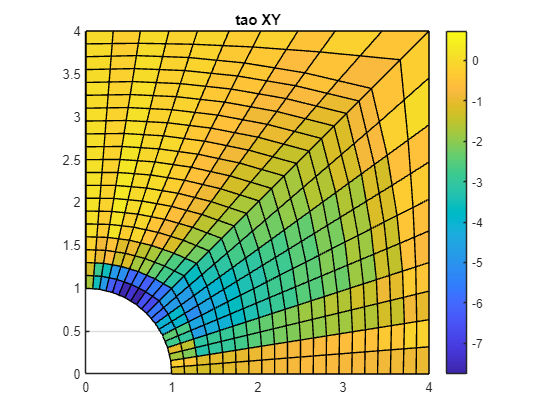

hold off